% Project 3 - Aircraft Descent Profile
%Benjamin Oakes - Engineering Computer Applications

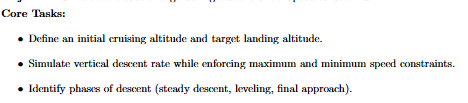

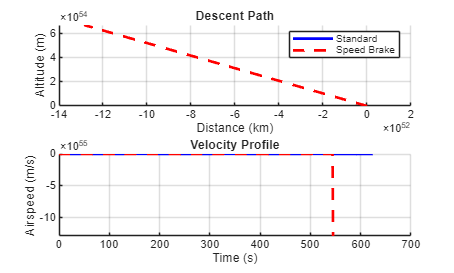


clear; %clears everything to prevent conflict from previously run code
clc; %Clears command window


g = 9.81;               % Gravity (m/s^2)
rho0 = 1.225;           % Sea level air density (kg/m^3)
H = 8500;               % Scale height (m)

% Aircraft Specs (Mid-size Jet)
m = 70000;              % Mass (kg)
S = 125;                % Wing area (m^2)
CD0_clean = 0.020;      % Zero-lift drag (clean)
delta_CD_sb = 0.040;    % Drag increase from speed brakes
K = 0.05;               % Induced drag factor
T_idle = 5000;          % Idle thrust (N)

h0 = 10000;             % Initial altitude (m)
v0 = 240;               % Initial TAS (m/s)
gamma = deg2rad(-3.0);  % 3-degree descent angle
h_final = 3000;         % Target altitude (m)
dt = 1.0;               % Time step (s)

scenarios = {'Standard', 'SpeedBrake'};
results = struct();

for i = 1:length(scenarios)
    mode = scenarios{i};
    CD0 = CD0_clean + (strcmp(mode, 'SpeedBrake') * delta_CD_sb);
    
    % Initial States
    t = 0; h = h0; v = v0; x = 0;
    t_h = []; h_h = []; v_h = []; x_h = [];
    
    while h > h_final
        t_h(end+1) = t; h_h(end+1) = h; v_h(end+1) = v; x_h(end+1) = x;
        
        rho = rho0 * exp(-h / H);
        L = m * g * cos(gamma);
        CL = L / (0.5 * rho * v^2 * S);
        CD = CD0 + K * CL^2;
        D = CD * (0.5 * rho * v^2 * S);
        
        % Acceleration along flight path
        dv_dt = (T_idle - D - m * g * sin(gamma)) / m;
        
        % Update
        v = v + dv_dt * dt;
        h = h + v * sin(gamma) * dt;
        x = x + v * cos(gamma) * dt;
        t = t + dt;
    end
    results.(mode).t = t_h; results.(mode).h = h_h; 
    results.(mode).v = v_h; results.(mode).x = x_h / 1000;
end

figure;
subplot(2,1,1); hold on;
plot(results.Standard.x, results.Standard.h, 'b', 'LineWidth', 2);
plot(results.SpeedBrake.x, results.SpeedBrake.h, 'r--', 'LineWidth', 2);
grid on; ylabel('Altitude (m)'); xlabel('Distance (km)');
legend('Standard', 'Speed Brake'); title('Descent Path');

subplot(2,1,2); hold on;
plot(results.Standard.t, results.Standard.v, 'b', 'LineWidth', 2);
plot(results.SpeedBrake.t, results.SpeedBrake.v, 'r--', 'LineWidth', 2);
grid on; ylabel('Airspeed (m/s)'); xlabel('Time (s)');
title('Velocity Profile');